# **Image Deblurring using ILSTAT-ADMM**

clc;clear;close all;
tic;

**Load image**

img=im2double(imread(['cameraman.tif']));
[n1,n2]=size(img);
N=n1*n2;

%Gaussian blur kernel
h=fspecial('gaussian',9,2);

%Forward and adjoint operators
A=@(x)imfilter(x,h,'circular');
AT=@(x)imfilter(x,h,'circular');


**Create blurred + noisy image**

b_img=A(img);
b_img=b_img+0.01*randn(size(img));
b=b_img(:);


**Parameters**

rho=1;
lambda=0.0003;     
maxIter=100;
tol=1e-6;
v=1.5;             

% Initialization
x=b;
y=b;
z=zeros(N,1);

err=zeros(maxIter,1);
obj=zeros(maxIter,1);


#### **ILSTAT-ADMM**

for k=1:maxIter
    x_old=x;
    
    %x-update 
    bk=y+z/rho;
    
    for j=1:40
        x_img=reshape(x,n1,n2);
        Hx=A(x_img);
        
        grad_img=AT(Hx-reshape(bk,n1,n2));
        grad=grad_img(:);
        
        %Properly scaled gradient step
        x_temp=x-(1/v)*grad;
        
        %LST shrinkage
        x=sign(x_temp).*max(abs(x_temp)-lambda,0);
    end
    
    %y-update
    Hx_vec=reshape(A(reshape(x,n1,n2)),[],1);
    y=(b+rho*Hx_vec-z)/(1+rho);
    
    %z-update
    z=z+rho*(y-Hx_vec);
    
    err(k)=norm(x-img(:));
    obj(k)=norm(y-b)^2-z'*(y-Hx_vec)+(rho/2)*norm(y-Hx_vec)^2;
    
    if norm(x-x_old)<tol
        err=err(1:k);
        obj=obj(1:k);
        break;
    end
end

runtime=toc;

%Reconstructed image
x_rec=reshape(x,n1,n2);

%PSNR
mse=mean((img(:)-x_rec(:)).^2);
psnr_value=10*log10(1/mse);

fprintf('PSNR=%.4f dB\n',psnr_value);

PSNR=17.8629 dB


fprintf('Runtime=%.4f seconds\n',runtime);

Runtime=5.8134 seconds


** Results**

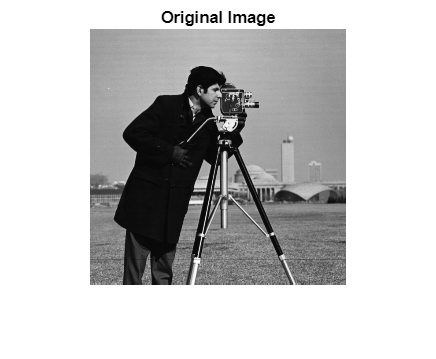

figure;imshow(img);title('Original Image');

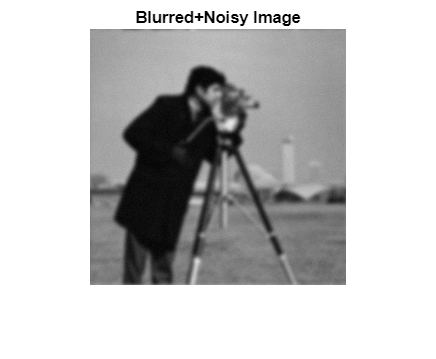


figure;imshow(b_img);title('Blurred+Noisy Image');

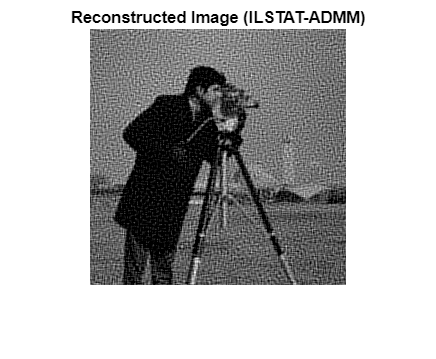


figure;imshow(x_rec,[]);title('Reconstructed Image (ILSTAT-ADMM)');

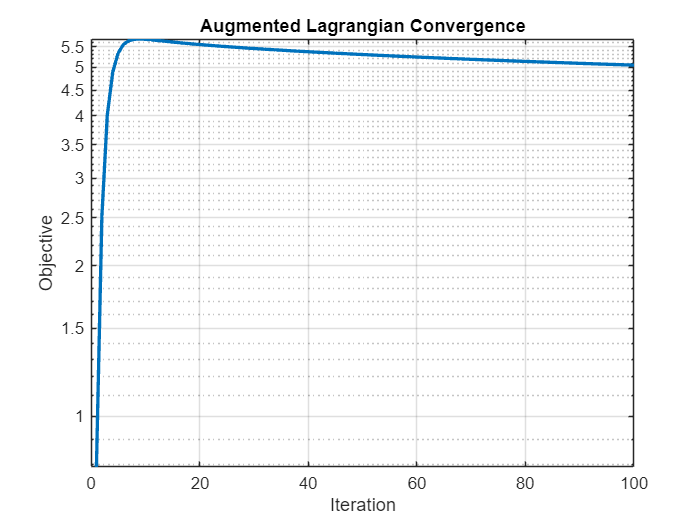


figure;
semilogy(obj,'LineWidth',2);
grid on;
title('Augmented Lagrangian Convergence');
xlabel('Iteration');
ylabel('Objective');